## State space representation

clear all
%addpath("C:\Users\nicol\OneDrive\Documents\34746 - Robust & Fault Tolerent Control\Exercises\SA Tool\SaTool_3_0100\sa_tool_3_0100");
load('ECP_values.mat');
load('ECP502Data.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

s = tf('s');
%syms s
A = [0 1 0 0 0 0
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 0
    1/J_1 0
    0 0
    0 1/J_2
    0 0
    0 0];
B = B(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:);

D = [0 0
     0 0
     0 0];
D=0;


state = ss(A,B,C,D);
G0_tf = tf(state);


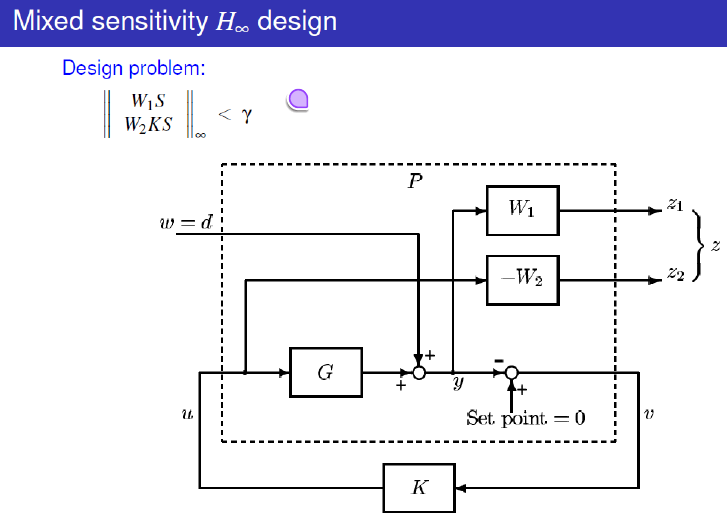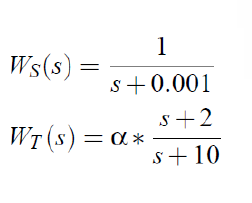

Ws = W1 

WT = W2

M_1 = 20;     % Stadig åben til fortolkning
A_1 = 0.0005;  % Looks OK
omega_star_1 = 1;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
M_2 = 10;     % Stadig åben til fortolkning
A_2 = 0.05;  % Looks OK
omega_star_2 = 12;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s



W1 = ((s/M_1 + omega_star_1) / (s + omega_star_1*A_1))^2;
W2 = ((s + omega_star_2*A_2) / (s/M_2 + omega_star_2))^2;  % Same weight on KS for now
W3 = tf(0);

gamRange = [0, 10];
[K_star,CL_star,gamma_star] = mixsyn(G0_tf,W1,W2,W3,gamRange);
gamma_star

gamma_star = 0.1506

pct = 2;
[K_2pct,CL_2pct,gamma_2pct] = mixsyn(G0_tf,W1,W2,W3,[(1 + pct/100)*gamma_star, (1 + pct/100)*gamma_star]);
gamma_2pct

gamma_2pct = 0.1536


[K_Hinf, Cl, Gam, Info] = mixsyn(G0_tf,(1/gamma_2pct) * W1,(1/gamma_2pct) * W2,W3,1);
Gam

Gam = 0.9995

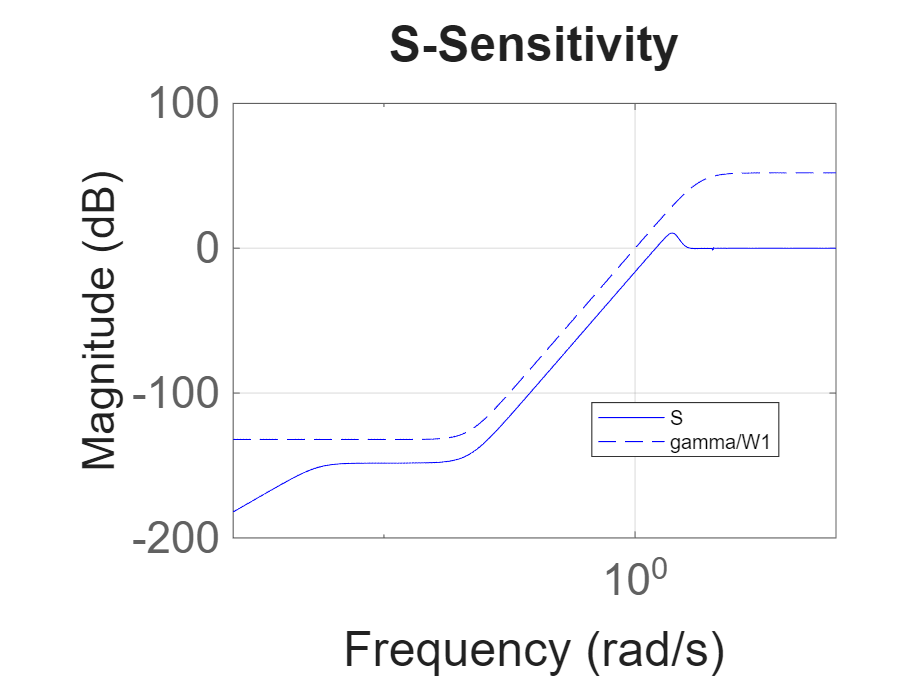


Cl = (G0_tf*K_Hinf)/(1+G0_tf*K_Hinf);

S_tf = feedback(1,G0_tf*tf(K_Hinf));


% Validation 

figure;
% Frequency vector from 10^-8 to 10^4 rad/s (logarithmically spaced)
w = logspace(-8, 4, 1000);  
bodemag(S_tf,'b',Gam/(W1),'b--',w);
grid on;
title('S-Sensitivity');
legend('S', 'gamma/W1','Location', 'best');

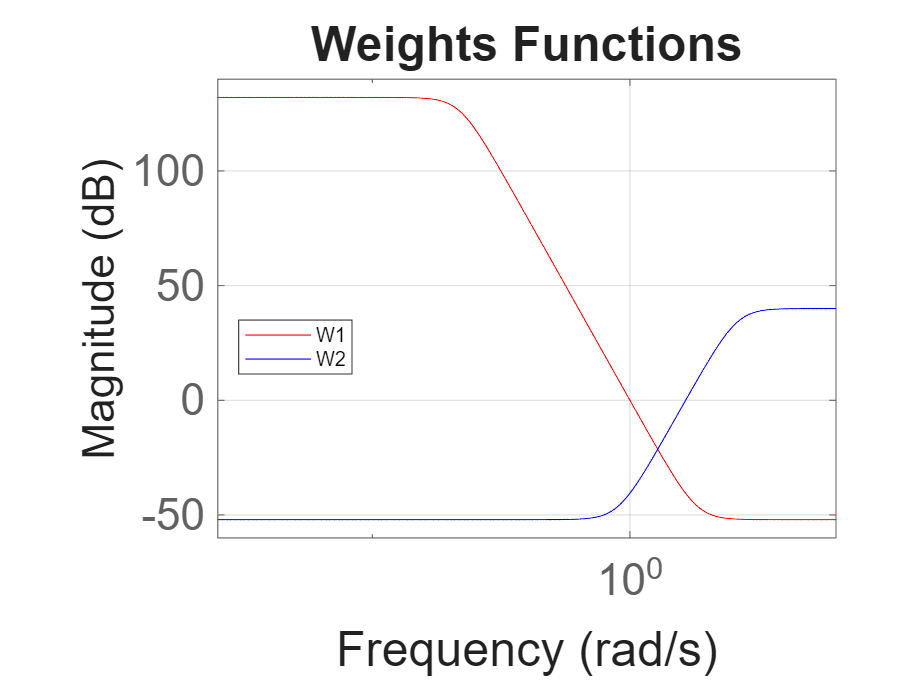


figure;
bodemag((W1),'r',(W2),'b',w);
grid on;
title('Weights Functions');
legend('W1', 'W2','Location', 'best');

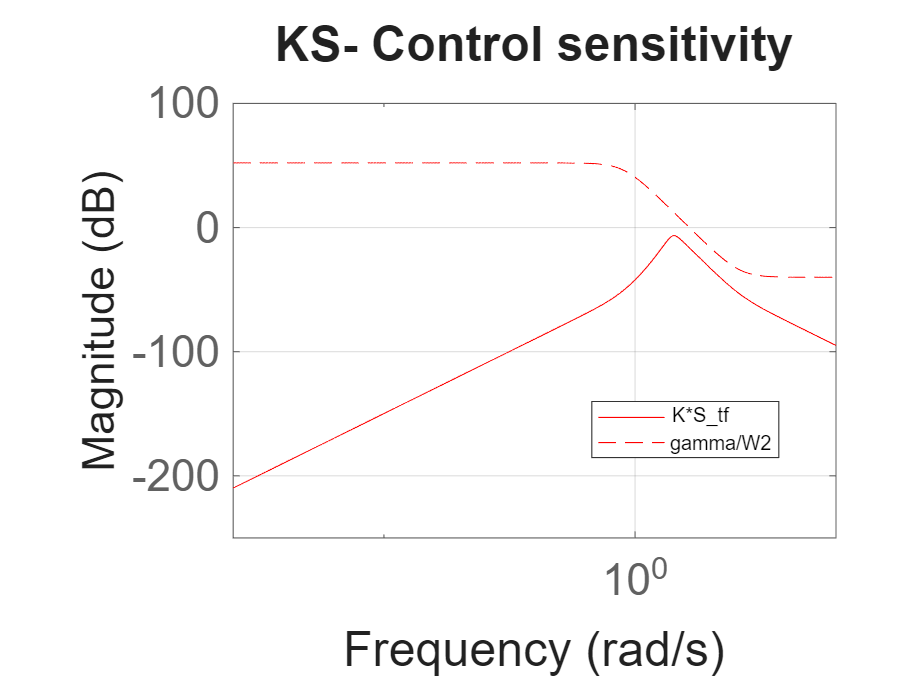



%saveas(gcf, 'figures/p1.png');
figure;
bodemag(K_Hinf*S_tf,'r',Gam/(W2),'r--',w);
legend('K*S_tf', 'gamma/W2','Location', 'best');
grid on;
title('KS- Control sensitivity');

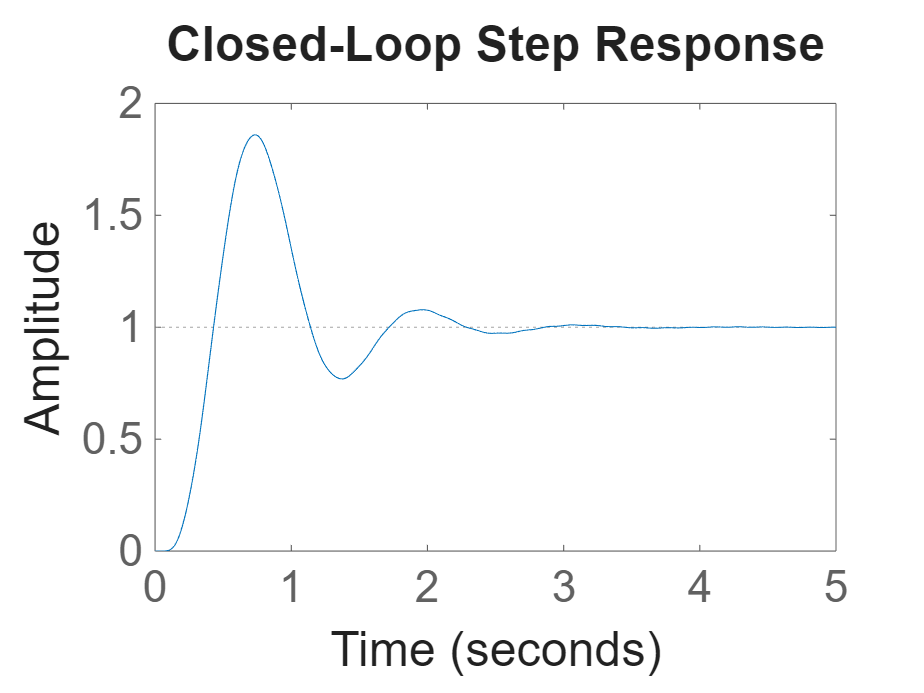



%saveas(gcf, 'figures/p2.png');
%%

% Analyze
figure;
t = 0:0.01:5;  % Time vector from 0 to 5 seconds with 0.01s resolution
step(Cl, t);
title('Closed-Loop Step Response');

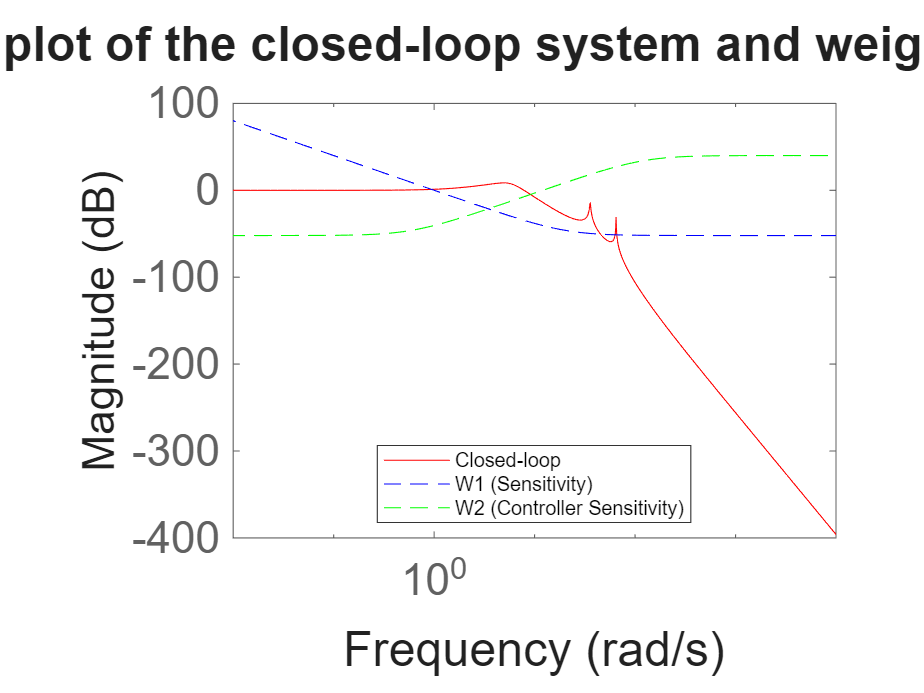




% Plot the closed-loop system
figure;
hold on;
bodemag(Cl, 'r'); 
bodemag(W1, 'b--');
bodemag(W2, 'g--');
legend('Closed-loop', 'W1 (Sensitivity)', 'W2 (Controller Sensitivity)', 'Location', 'best');
title('Bode plot of the closed-loop system and weight functions');

Question 10

% Reduce the controller order

order_desired = 7;  % Try 6th order
%K_reduced = reduce(K_Hinf, order_desired);
size(K_Hinf)

State-space model with 1 outputs, 1 inputs, and 10 states.


K_reduced = hankelmr(K_Hinf, order_desired);
size(K_reduced)

State-space model with 1 outputs, 1 inputs, and 7 states.


Cl_reduced = feedback(G0_tf, K_reduced);
size(G0_tf)

Transfer function with 1 outputs and 1 inputs.


eig(Cl_reduced)

ans =   -0.1188 +64.6906i
  -0.1188 -64.6906i
  -0.3461 +35.7302i
  -0.3461 -35.7302i
  -0.2853 +35.7755i
  -0.2853 -35.7755i
  -1.8074 + 5.4246i
  -1.8074 - 5.4246i
  -4.9640 + 3.5618i
  -4.9640 - 3.5618i


% Check poles
poles_Cl_reduced = pole(Cl_reduced);


% Poles and zeros of full controller
poles_full = pole(K_Hinf);
zeros_full = zero(K_Hinf)

zeros_full = 1.0e+02 *

  -1.2000 + 0.0000i
  -1.2000 - 0.0000i
  -0.0181 + 0.0000i
  -0.0012 + 0.6469i
  -0.0012 - 0.6469i
  -0.0000 + 0.0000i
  -0.0031 + 0.3574i
  -0.0031 - 0.3574i
  -0.0053 + 0.0000i



% Poles and zeros of reduced controller
poles_reduced = pole(K_reduced);
zeros_reduced = zero(K_reduced)

zeros_reduced = 1.0e+02 *

  -1.1922 + 0.0000i
  -0.0032 + 0.3577i
  -0.0032 - 0.3577i
  -0.0180 + 0.0000i
  -0.0053 + 0.0000i
  -0.0000 + 0.0000i


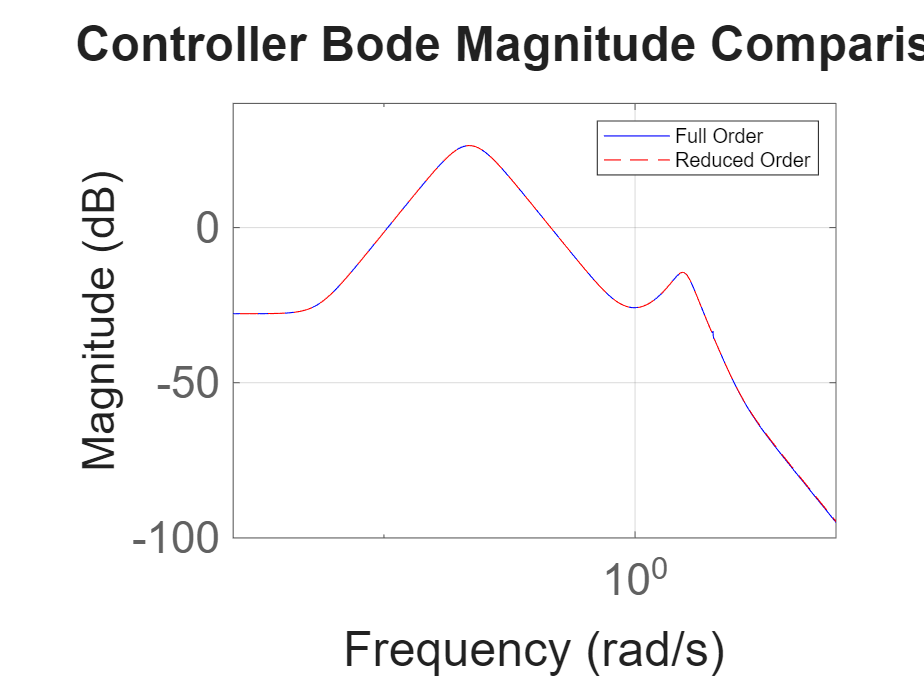



figure;
bodemag(K_Hinf, 'b', K_reduced, 'r--');
legend('Full Order', 'Reduced Order');
title('Controller Bode Magnitude Comparison');
grid on;

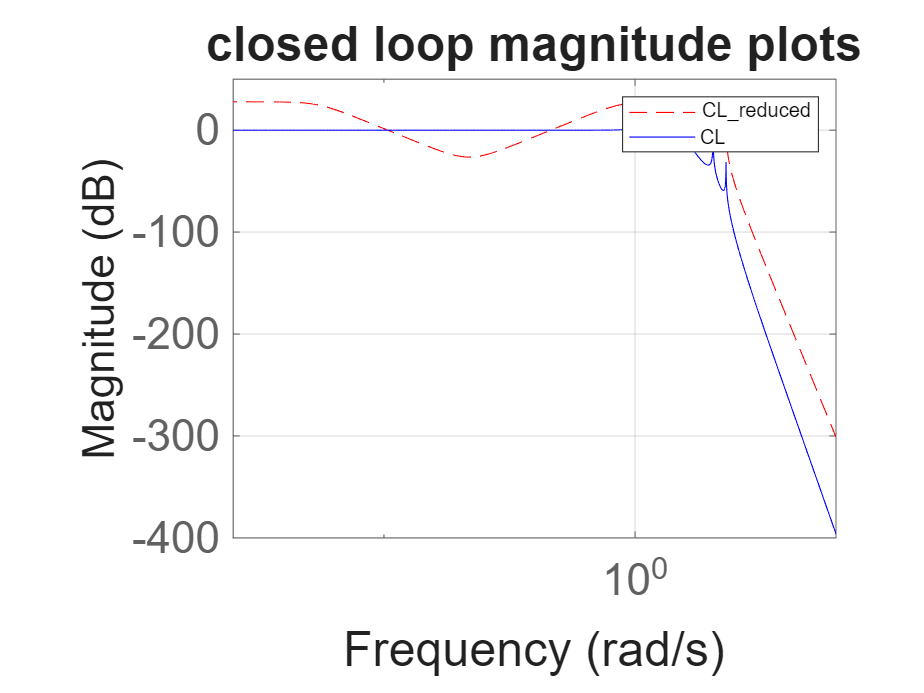

figure; 
bodemag(Cl_reduced,'r--',Cl,'b')
legend('CL_reduced','CL');
title('closed loop magnitude plots');
grid on; 

Question 11

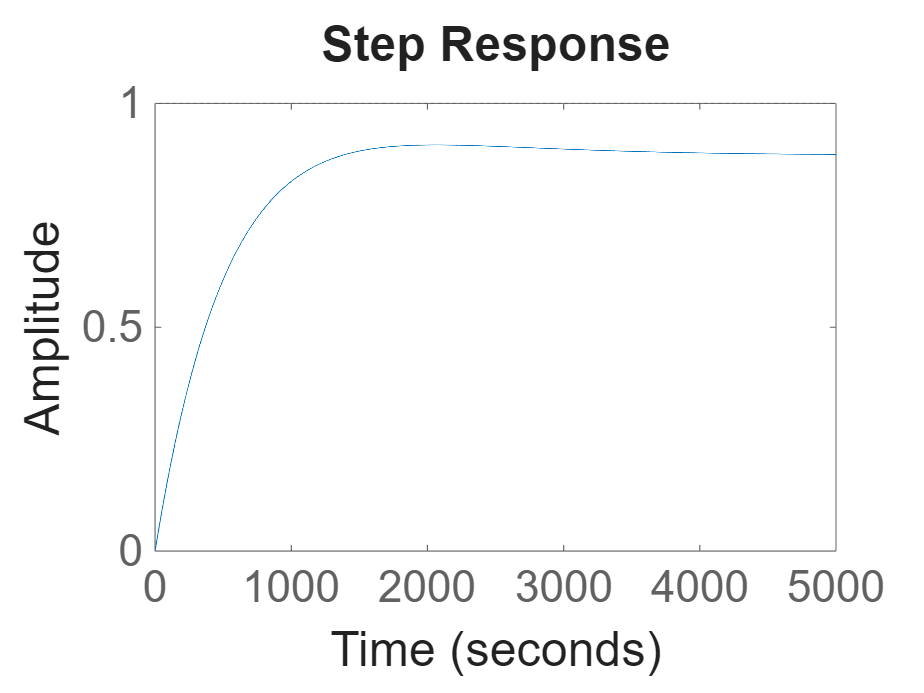


% Large gamma bounds, no minimization – "h2-like" behavior
[K_H2, CL_H2, gamma_H2, info_H2] = mixsyn(G0_tf, W1, W2, 1e6);
%Compare closed loop transfer functions
CL_Hinf = feedback(G0_tf * K_Hinf, 1);
CL_H2 = feedback(G0_tf * K_H2, 1);

step(CL_H2);

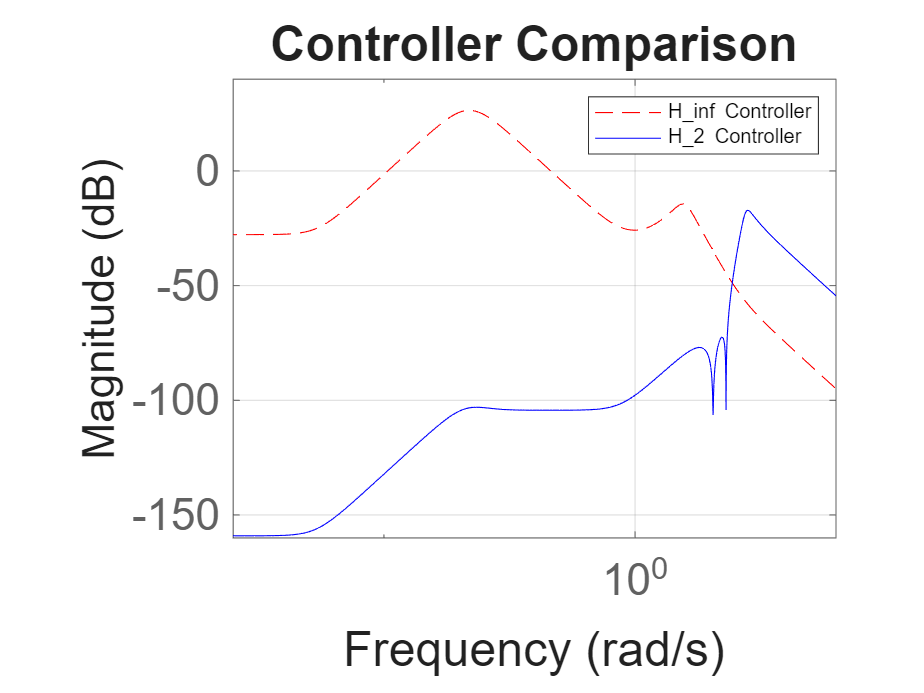


% Compare controllers 
figure;
bodemag(K_Hinf, 'r--', K_H2, 'b');
legend('H_inf Controller', 'H_2 Controller');
title('Controller Comparison');
grid on;

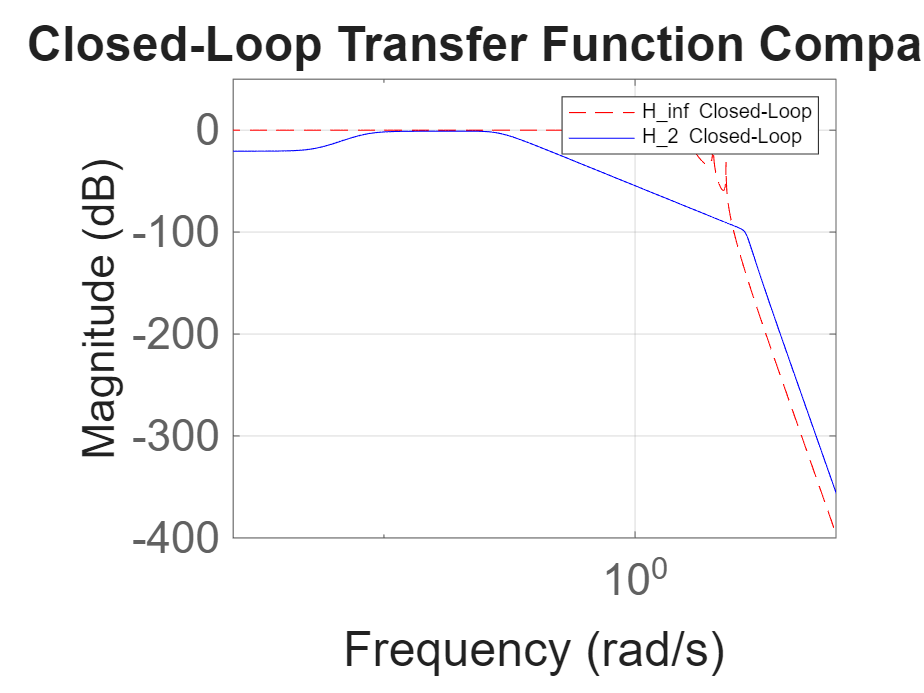




figure;
bodemag(CL_Hinf, 'r--', CL_H2, 'b');
legend('H_inf Closed-Loop', 'H_2 Closed-Loop');
title('Closed-Loop Transfer Function Comparison');
grid on;

Question 12

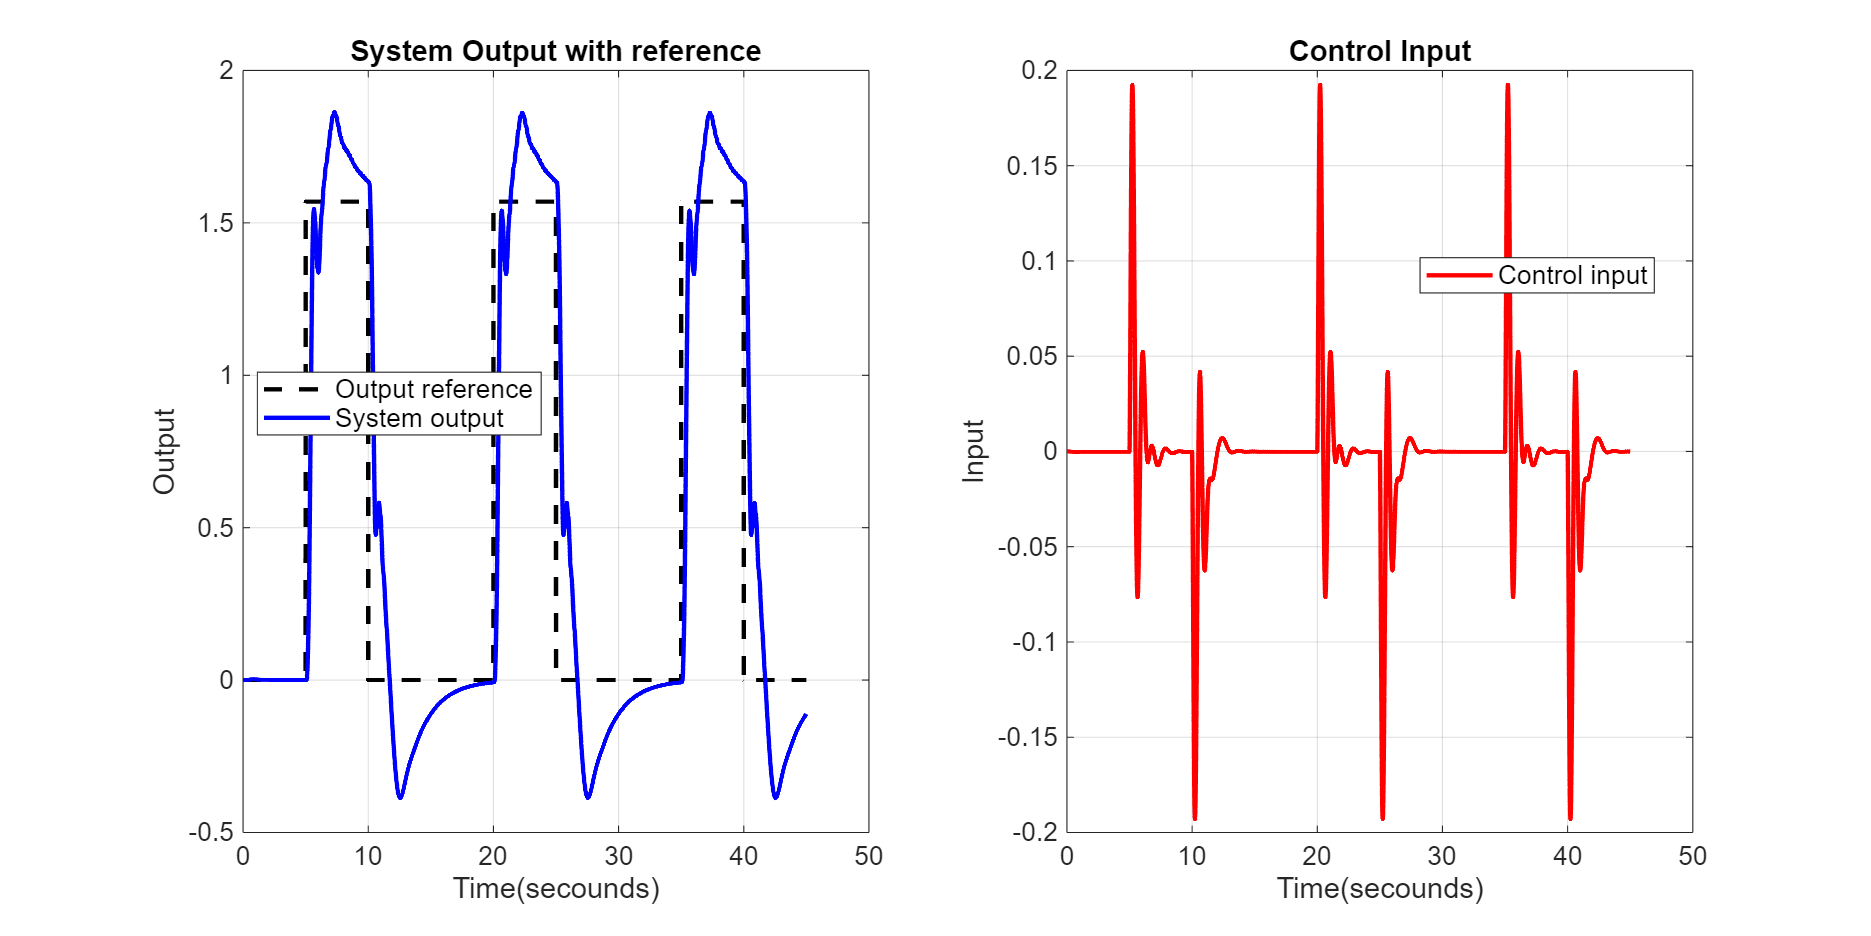

% Export controller
% K = ss(K_reduced);  % or K_Hinf if not reduced
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
simTime = 45;                   % Simulation duration in seconds
d = zeros(simTime/T_s,0);
t = 0:T_s:simTime;
d_in = [t d];

sim_out_nominel_old = sim('Opg12_simulink_model.slx');
y_nominel_old = sim_out_nominel_old.y.Data(:,1);
u_nominel_old = sim_out_nominel_old.u.Data;
ref = sim_out_nominel_old.y.Data(:,2);
t = 0:T_s:simTime;
% Create figure
figure;

% Left plot: Output and Reference
subplot(1,2,1);
plot(t, ref, 'k--', 'LineWidth', 2); hold on;  % Increased line width
plot(t, y_nominel_old, 'b', 'LineWidth', 2);  % Increased line width
title('System Output with reference', 'FontSize', 14);      % Increased font size
xlabel('Time(secounds)', 'FontSize', 12);         % Increased font size
ylabel('Output', 'FontSize', 12);            % Increased font size
legend('Output reference', 'System output', 'Location', 'best', 'FontSize', 12);  % Increased font size
grid on;
set(gca, 'FontSize', 12);  % Increased axis font size

% Right plot: Input
subplot(1,2,2);
plot(t, u_nominel_old, 'r', 'LineWidth', 2);  % Increased line width
title('Control Input', 'FontSize', 14);      % Increased font size
xlabel('Time(secounds)', 'FontSize', 12);         % Increased font size
ylabel('Input', 'FontSize', 12);             % Increased font size
legend('Control input', 'Location', 'best', 'FontSize', 12);  % Increased font size
grid on;
set(gca, 'FontSize', 12);  % Increased axis font size

% Save figure as full page
set(gcf, 'PaperPositionMode', 'auto');  % Auto adjust paper size to match figure size
set(gcf, 'Position', [100, 100, 1200, 600]);  % Adjust figure window size (in pixels)

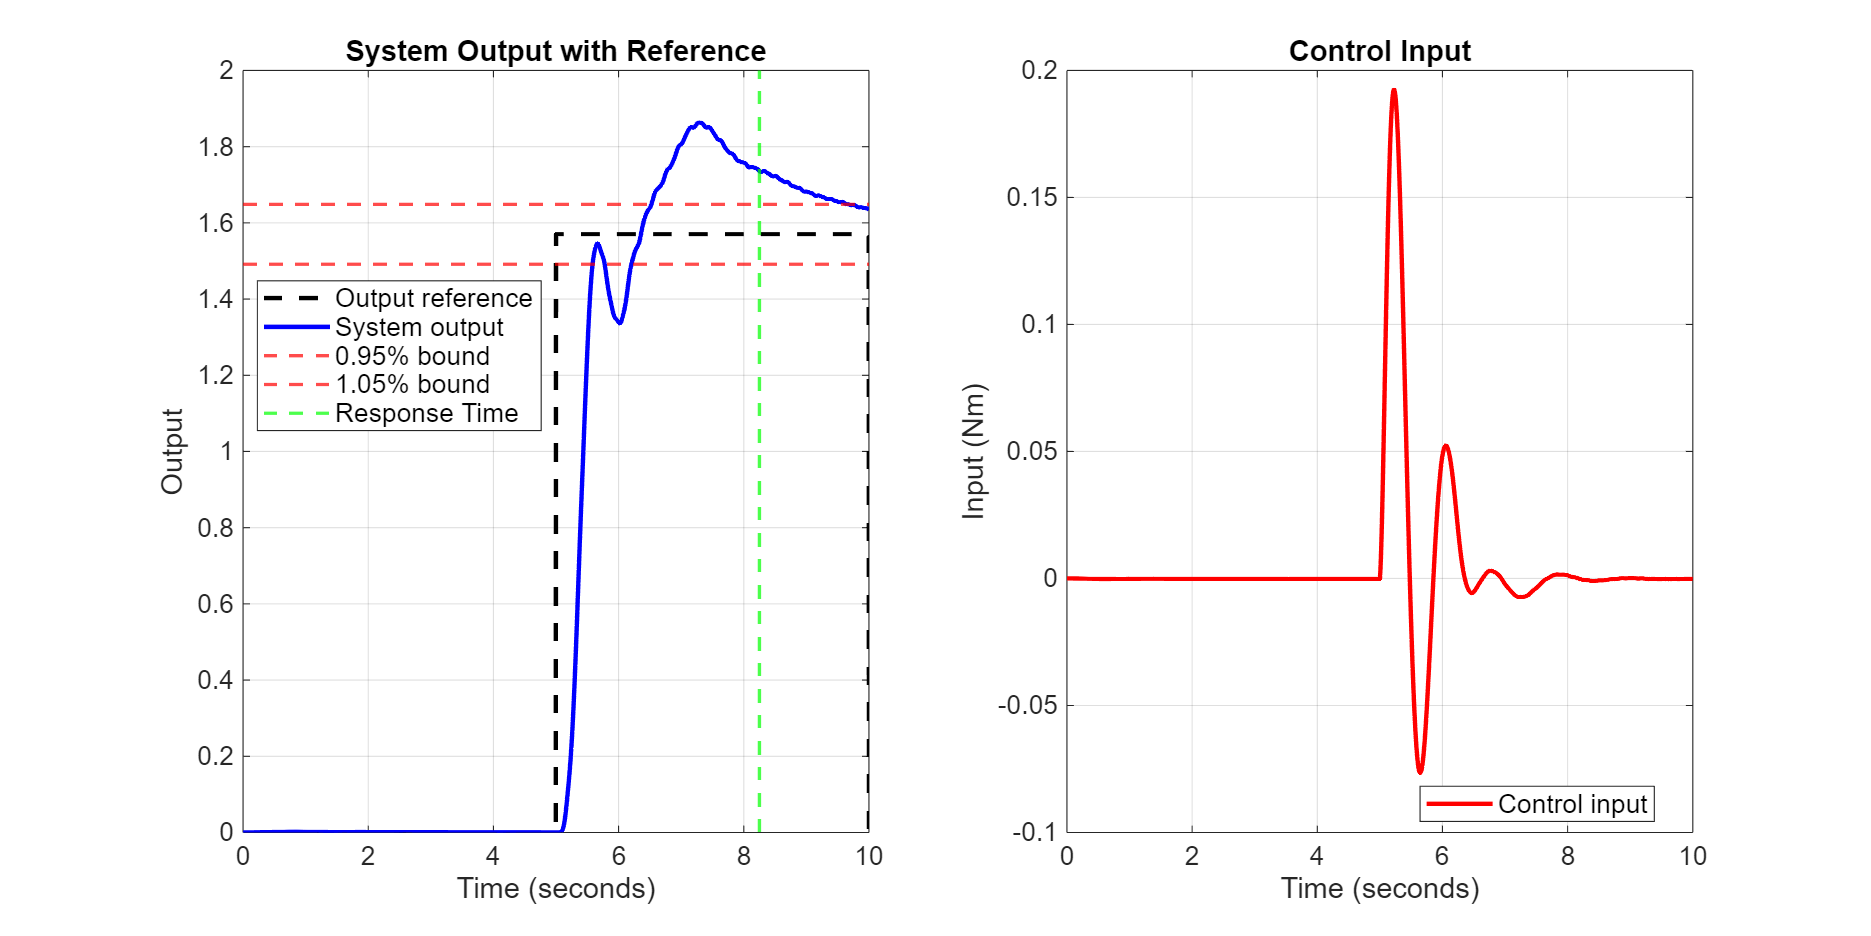

%saveas(gcf, fullfile('C:\Users\nicol\Robust-and-Fault-tolerant-Control\Mandatory Assignment 2025 - Part B\figures', 'opg12_output_and_input_plot.png'));  % Save as PNG
% Define the final value of the step and tolerance band
figure;
% Left plot: Output and Reference
subplot(1,2,1);
plot(t(t <= 10), ref(t <= 10), 'k--', 'LineWidth', 2); hold on;  % Plot reference, only from 0 to 10 seconds
plot(t(t <= 10), y_nominel_old(t <= 10), 'b', 'LineWidth', 2);  % Plot system output, only from 0 to 10 seconds
yline(1.57 * 1.05, 'r--', 'LineWidth', 1.5);  % Upper bound
yline(1.57 * 0.95, 'r--', 'LineWidth', 1.5);  % Lower bound

xline(8.25, 'g--', 'LineWidth', 1.5);
title('System Output with Reference', 'FontSize', 14);      % Increased font size
xlabel('Time (seconds)', 'FontSize', 12);         % Increased font size
ylabel('Output', 'FontSize', 12);            % Increased font size
legend('Output reference', 'System output', '0.95% bound','1.05% bound','Response Time', 'Location', 'best', 'FontSize', 12);  % Increased font size
grid on;
set(gca, 'FontSize', 12);  % Increased axis font size

% Right plot: Input
subplot(1,2,2);
plot(t(t <= 10), u_nominel_old(t <= 10), 'r', 'LineWidth', 2);  % Plot control input, only from 0 to 10 seconds
title('Control Input', 'FontSize', 14);      % Increased font size
xlabel('Time (seconds)', 'FontSize', 12);         % Increased font size
ylabel('Input (Nm)', 'FontSize', 12);             % Increased font size
legend('Control input', 'Location', 'best', 'FontSize', 12);  % Increased font size
grid on;
set(gca, 'FontSize', 12);  % Increased axis font size

% Save figure as full page
set(gcf, 'PaperPositionMode', 'auto');  % Auto adjust paper size to match figure size
set(gcf, 'Position', [100, 100, 1200, 600]);  % Adjust figure window size (in pixels)

%saveas(gcf, fullfile('C:\Users\nicol\Robust-and-Fault-tolerant-Control\Mandatory Assignment 2025 - Part B\figures', 'opg12_output_and_input_plot_zoom.png'));  % Save as PNG





Question 13

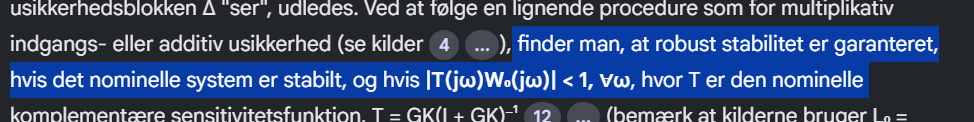

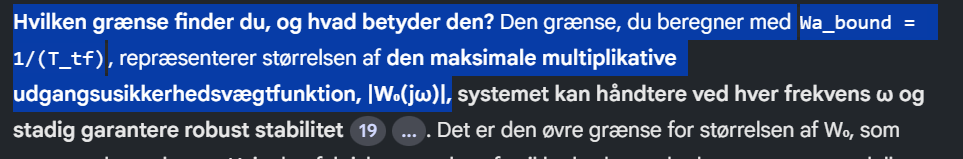


%Wa_upper = 1/abs(K_reduced*(eye(size(G0_tf))+G0_tf*K_reduced))    L14
figure;
%T_tf = (G0_tf*K_reduced)/(1+G0_tf*K_reduced);
T_tf = feedback(G0_tf*K_reduced,1)


T_tf =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14
   x1       -1.391      -85.37       -2.83      -40.81      -5.426  -2.509e-12       2.961       2.413      -29.26      -65.88      -24.13      -11.63         -12      -2.801
   x2           64           0           0           0           0           0           0           0           0           0           0           0           0           0
   x3            0          32           0           0           0           0           0           0           0           0           0           0           0           0
   x4            0           0          64           0           0           0           0           0           0           0           0           0           0           0
   x5            0           0           0           4           0           0           0           0      

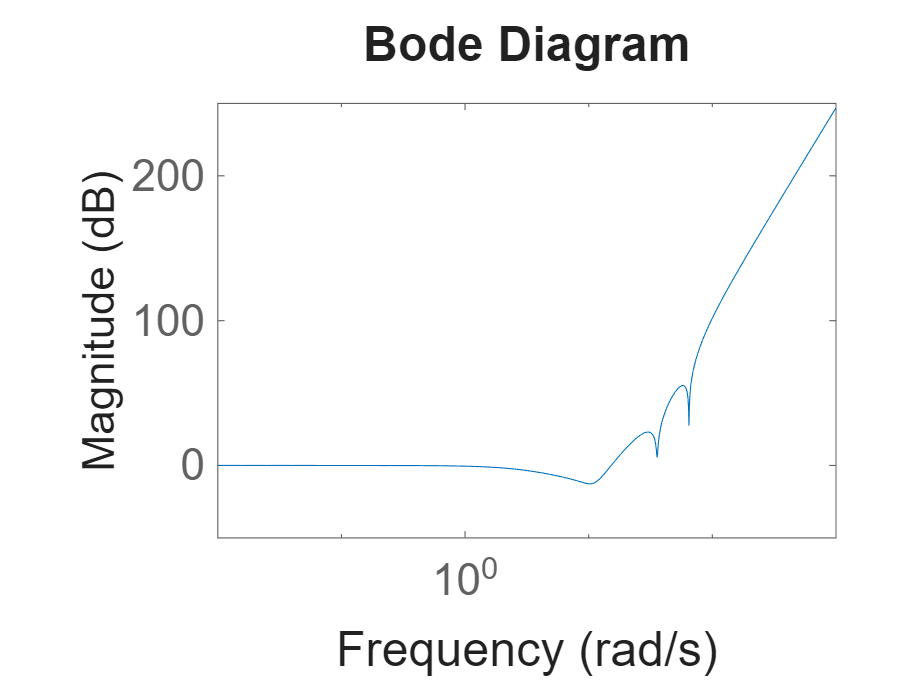

Wa_upper = 1/(T_tf);
Wa_tf = ss2tf(Wa_upper.A,Wa_upper.B,Wa_upper.C,Wa_upper.D);
bodemag(Wa_upper)

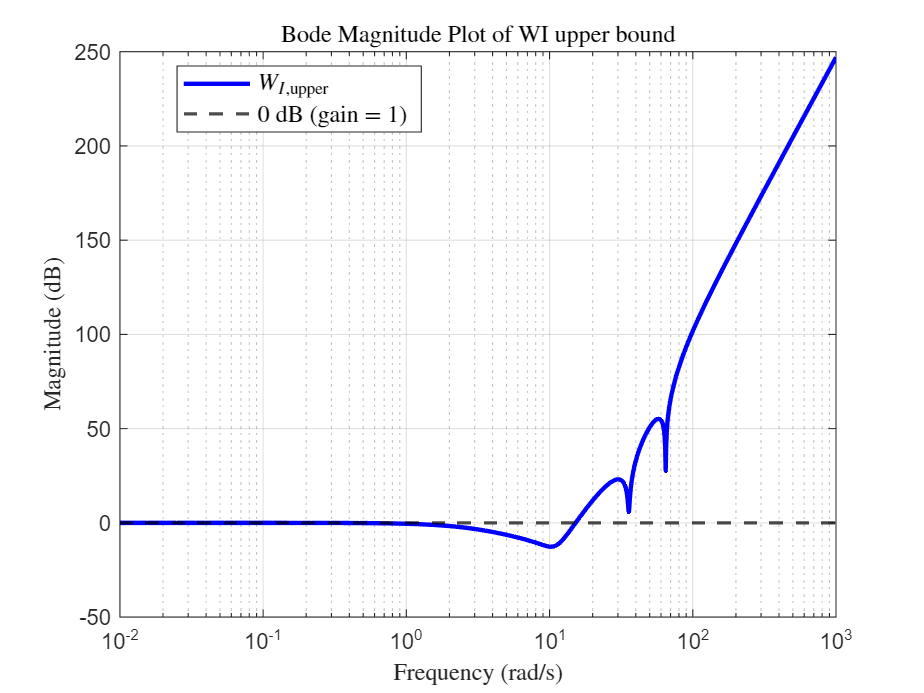

figure;
[mag, ~, w] = bode(Wa_upper);
mag_dB = 20*log10(squeeze(mag));
semilogx(w, mag_dB, 'b', 'LineWidth', 2); hold on;
yline(0, 'k--', 'LineWidth', 1.5);  % Reference line at 0 dB

% Beautify plot
grid on;
xlabel('Frequency (rad/s)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Bode Magnitude Plot of WI upper bound', 'Interpreter', 'latex');
legend({'$W_{I,\mathrm{upper}}$', '0 dB (gain = 1)'}, ...
       'Interpreter', 'latex', 'FontSize', 11, 'Location', 'best');
saveas(gcf, fullfile('C:\Users\nicol\Robust-and-Fault-tolerant-Control\Mandatory Assignment 2025 - Part B\figures', 'opg13_Wupper.png'));  % Save as PNG

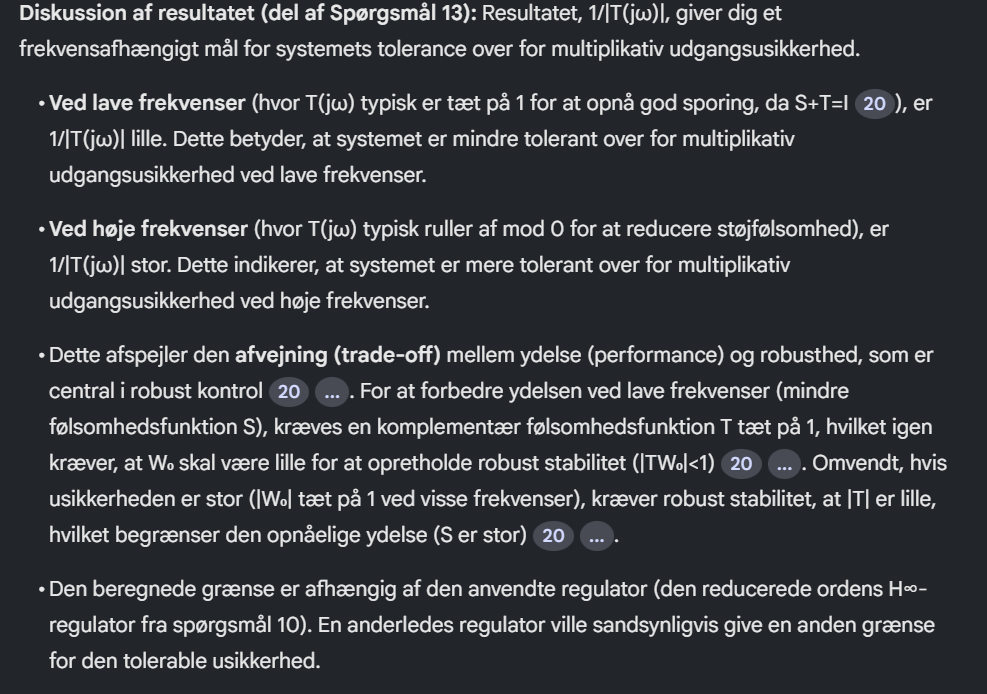 - crazy ai svar (good) 

% 
% % T: Complementary sensitivity function using reduced-order H_inf controller
% T_red = feedback(G0_tf * K_reduced, 1);
% 
% % Compute maximum gain of T (peak of magnitude)
% [mag_T, freq_T] = norm(T_red, inf);
% 
% % Max multiplicative uncertainty that can be tolerated
% max_uncertainty = 1 / mag_T;
% 
% fprintf('Max allowable multiplicative uncertainty at the output: %.4f\n', max_uncertainty);
% 
% % Plot T and compare with 1/W_Delta
% figure;
% bodemag(T_red, 'b', 'LineWidth', 1.5);
% hold on;
% bodemag(1/mag_T, 'r--', 'LineWidth', 1.5);
% legend('|T|', '1 / ||T||_∞ bound');
% title('Complementary Sensitivity and Robust Stability Bound');
% grid on;

Question 14

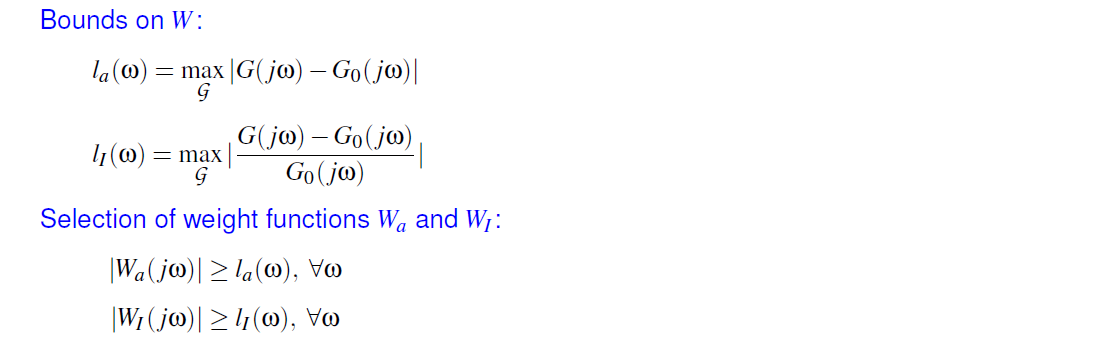

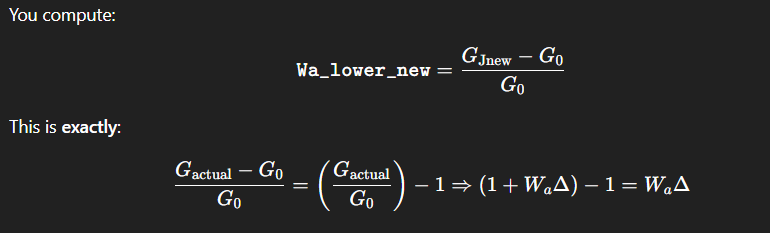 = derivation betweeen actual and norminal system. adn then normalized. 

J_1_new = 0.0325;
%syms s
A_new = [0 1 0 0 0 0
    -k_1/J_1_new -b_1/J_1_new k_1/J_1_new 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B_new = [0 0
    1/J_1_new 0
    0 0
    0 1/J_2
    0 0
    0 0];
B_new = B_new(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:);

D = [0 0
     0 0
     0 0];
D=0;

state_Jnew = ss(A_new,B_new,C,D);
G_Jnew = tf(state_Jnew);
T_tf_new = (G_Jnew*K_reduced)/(1+G_Jnew*K_reduced);
Wa_upper_new = 1/(T_tf_new);
Wa_lower_new = (G_Jnew-G0_tf)/(G0_tf);

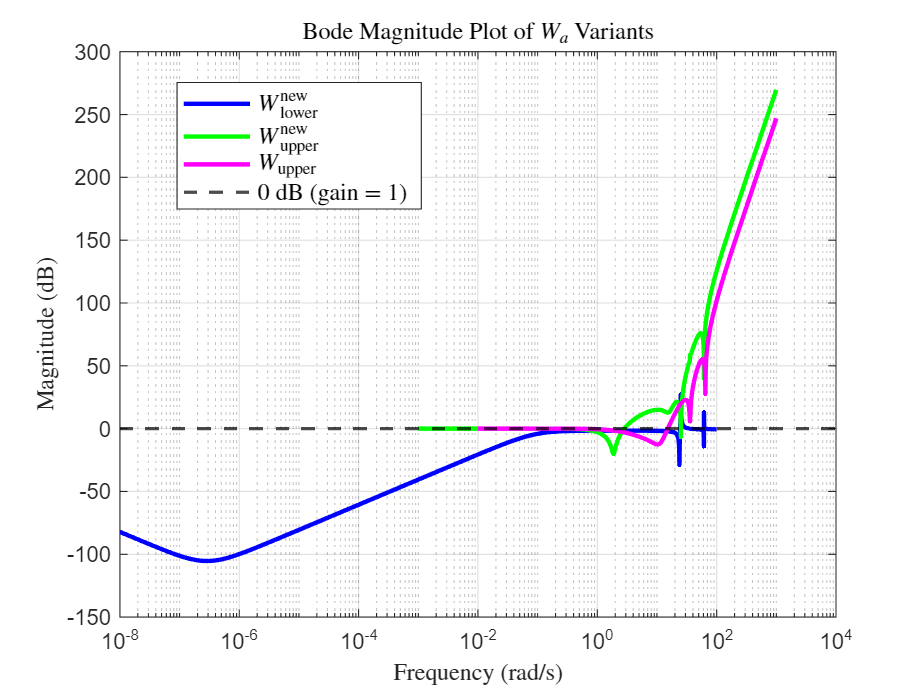

[mag1, ~, w1] = bode(Wa_lower_new);
mag1_dB = 20*log10(squeeze(mag1));
[mag2, ~, W2] = bode(Wa_upper_new);
mag2_dB = 20*log10(squeeze(mag2));
[mag3, ~, W3] = bode(Wa_upper);
mag3_dB = 20*log10(squeeze(mag3));

figure;
semilogx(w1, mag1_dB, 'b', 'LineWidth', 2); hold on;
semilogx(W2, mag2_dB, 'g', 'LineWidth', 2);
semilogx(W3, mag3_dB, 'm', 'LineWidth', 2);
yline(0, 'k--', 'LineWidth', 1.5);

grid on;
xlabel('Frequency (rad/s)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Bode Magnitude Plot of $W_a$ Variants', 'Interpreter', 'latex');

legend({'$W_{\mathrm{lower}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}$', ...
        '0 dB (gain = 1)'}, ...
        'Interpreter', 'latex', 'FontSize', 11, 'Location', 'best');

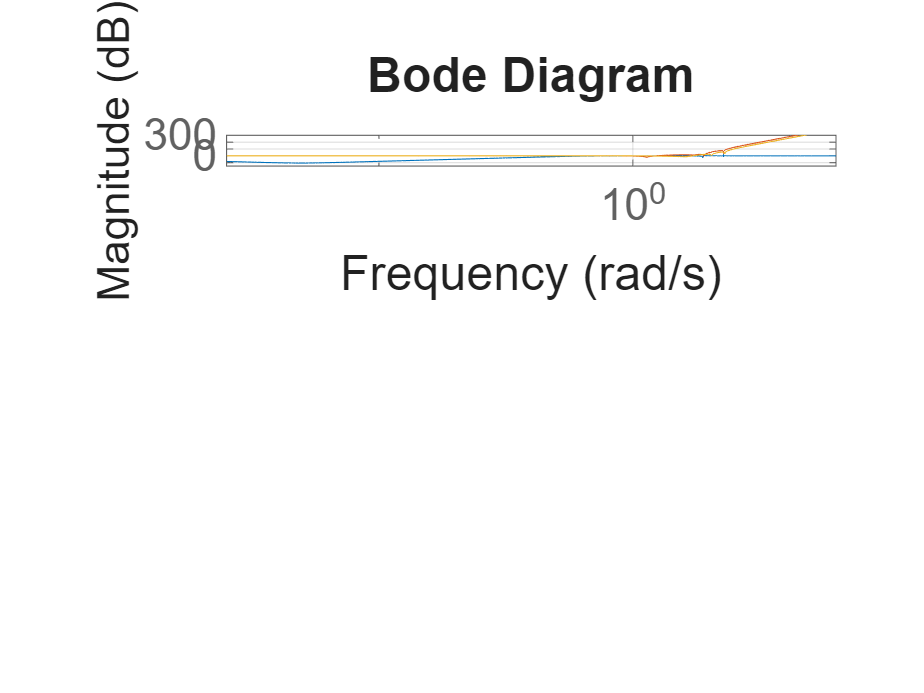


figure;

% Create the first subplot for the full frequency range
subplot(2, 1, 1);  % 2 rows, 1 column, first subplot
bodemag(Wa_lower_new, Wa_upper_new, Wa_upper);
grid on;

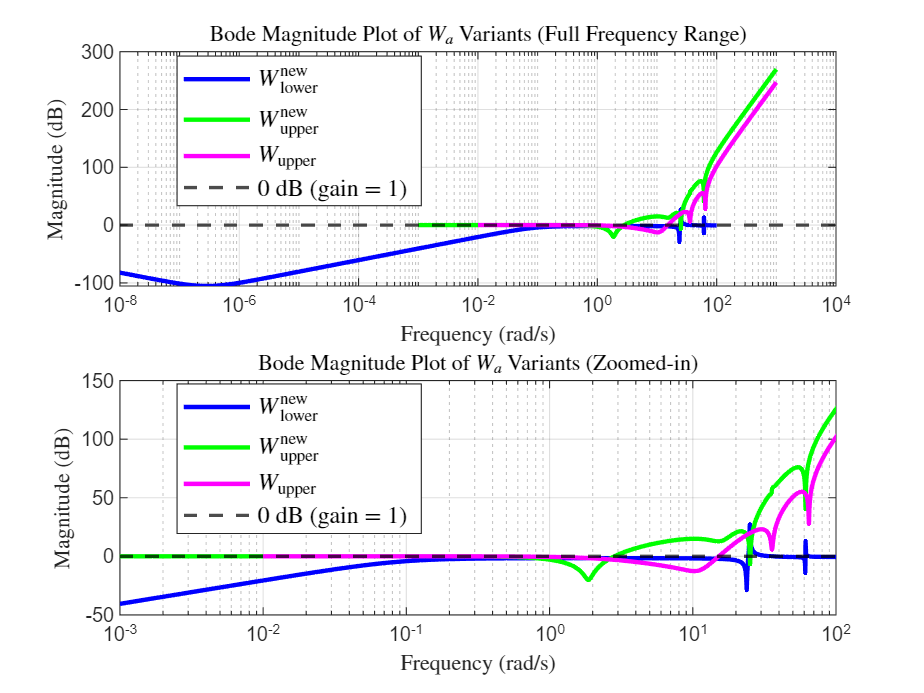

% Compute Bode data for the systems
[mag1, ~, w1] = bode(Wa_lower_new);
mag1_dB = 20*log10(squeeze(mag1));

[mag2, ~, W2] = bode(Wa_upper_new);
mag2_dB = 20*log10(squeeze(mag2));

[mag3, ~, W3] = bode(Wa_upper);
mag3_dB = 20*log10(squeeze(mag3));

% Create the figure with two subplots
figure;

% First subplot: Full frequency range
subplot(2, 1, 1);  % 2 rows, 1 column, first subplot
semilogx(w1, mag1_dB, 'b', 'LineWidth', 2); hold on;
semilogx(W2, mag2_dB, 'g', 'LineWidth', 2);
semilogx(W3, mag3_dB, 'm', 'LineWidth', 2);
yline(0, 'k--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (rad/s)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Bode Magnitude Plot of $W_a$ Variants (Full Frequency Range)', 'Interpreter', 'latex');
legend({'$W_{\mathrm{lower}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}$', ...
        '0 dB (gain = 1)'}, 'Interpreter', 'latex', 'FontSize', 11, 'Location', 'best');

% Second subplot: Zoomed-in frequency range (1e-1 to 1e2)
subplot(2, 1, 2);  % 2 rows, 1 column, second subplot
semilogx(w1, mag1_dB, 'b', 'LineWidth', 2); hold on;
semilogx(W2, mag2_dB, 'g', 'LineWidth', 2);
semilogx(W3, mag3_dB, 'm', 'LineWidth', 2);
yline(0, 'k--', 'LineWidth', 1.5);
xlim([1e-3, 1e2]);  % Zoom in on the frequency range from 10^-1 to 10^2
grid on;
xlabel('Frequency (rad/s)', 'Interpreter', 'latex');
ylabel('Magnitude (dB)', 'Interpreter', 'latex');
title('Bode Magnitude Plot of $W_a$ Variants (Zoomed-in)', 'Interpreter', 'latex');
legend({'$W_{\mathrm{lower}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}^{\mathrm{new}}$', ...
        '$W_{\mathrm{upper}}$', ...
        '0 dB (gain = 1)'}, 'Interpreter', 'latex', 'FontSize', 11, 'Location', 'best');

% Save the figure as an image file
saveas(gcf, fullfile('C:\Users\nicol\Robust-and-Fault-tolerant-Control\Mandatory Assignment 2025 - Part B\figures', 'opg14_bounds.png'));  % Save as PNG

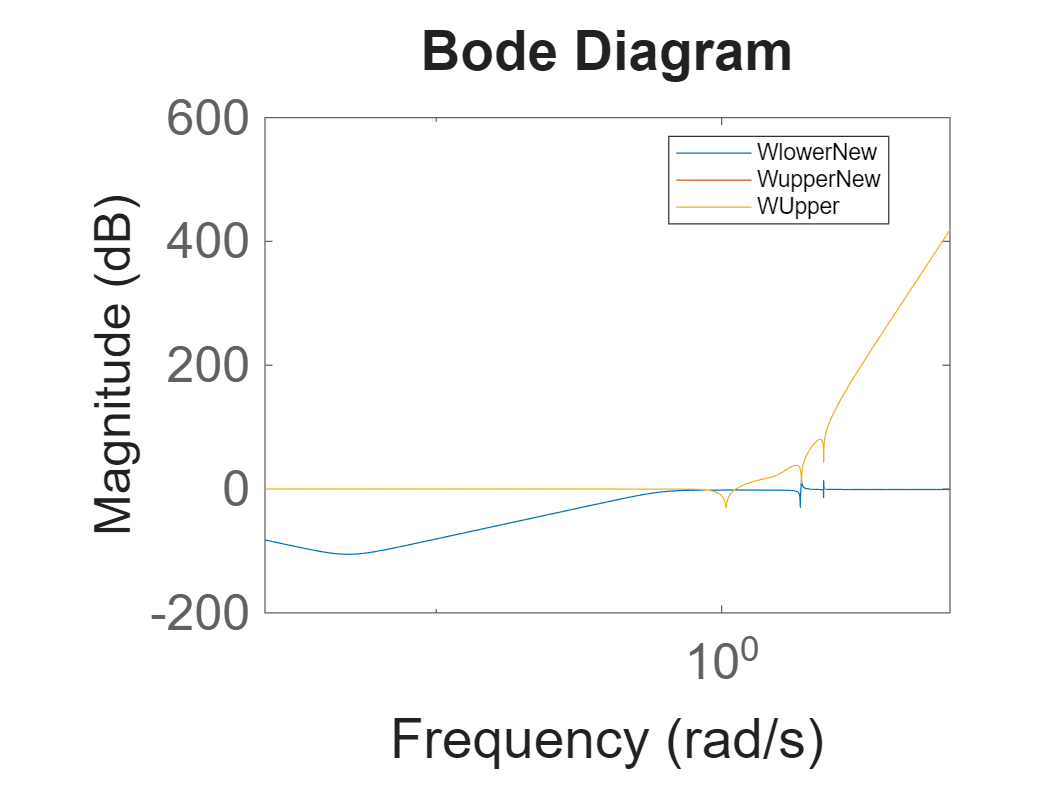


figure
bodemag(Wa_lower_new,Wa_upper_new,Wa_upper_new)
legend('WlowerNew', 'WupperNew', 'WUpper', 'Location', 'best');

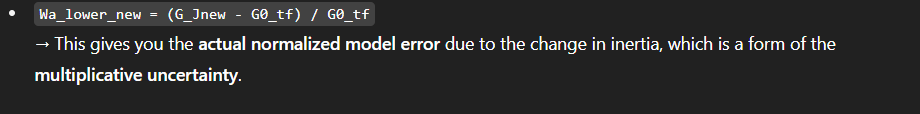

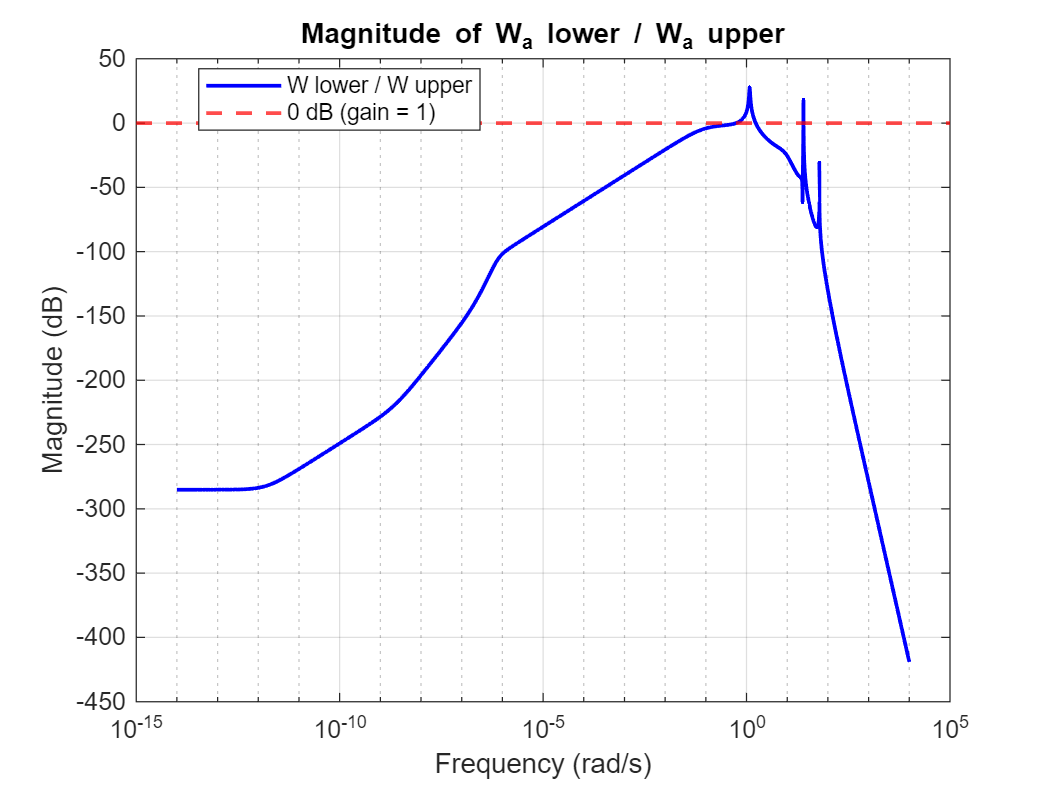

figure;
[mag, phase, w] = bode(Wa_lower_new / Wa_upper_new);
mag_dB = 20*log10(squeeze(mag));

semilogx(w, mag_dB, 'b', 'LineWidth', 1.5); % Plot magnitude in dB
hold on;
yline(0, 'r--', 'LineWidth', 1.5);          % Add horizontal line at 0 dB
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Magnitude of W_a lower / W_a upper');
legend('W lower / W upper', '0 dB (gain = 1)', 'Location', 'best');

from chad: 

% % Reuse original A, B, C, D
% A_nom = A;
% A_new = A;
% J1_nom = 0.0025;
% J1_new = 0.0325;
% 
% % Replace the relevant A matrix entries for J1 in perturbed model
% A_new(2,:) = [-k_1/J1_new -b_1/J1_new k_1/J1_new 0 0 0];
% B_new = [0; 1/J1_new; 0; 0; 0; 0];
% 
% % Create systems
% G0 = ss(A_nom, B, C, D);
% G_new = ss(A_new, B_new, C, D);
% 
% % Compute transfer functions
% G0_tf = tf(G0);
% Gnew_tf = tf(G_new);
% 
% % Frequency range
% omega = logspace(-1, 2, 500);
% [mag_G0, ~] = bode(G0_tf, omega);
% [mag_Gnew, ~] = bode(Gnew_tf, omega);
% 
% % Compute multiplicative uncertainty (element-wise)
% mag_G0 = squeeze(mag_G0);
% mag_Gnew = squeeze(mag_Gnew);
% WI = abs((mag_Gnew - mag_G0) ./ mag_G0);
% 
% % Plot result
% figure;
% semilogx(omega, WI, 'b', 'LineWidth', 1.5);
% xlabel('Frequency [rad/s]');
% ylabel('|Δ(jω)|');
% title('Lower bound for uncertainty weight W_I');
% grid on;
% 
% % Compare to previous max allowed uncertainty
% yline(max_uncertainty, 'r--', 'LineWidth', 1.5);
% legend('|Δ(jω)| from J1 change', 'Max allowed from Q13');
% 

Question 15

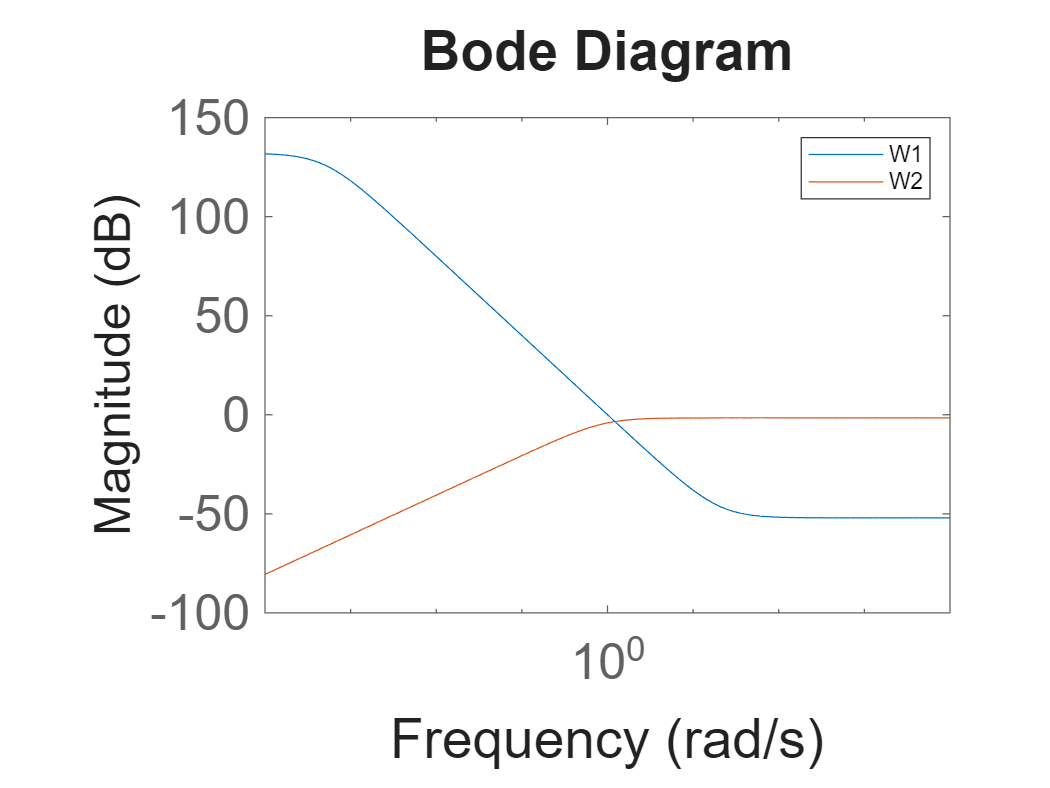

%figure
%bodemag(WI,Wa_upper_new,Wa_lower_new)
%legend("'test",'upper','lower')
%s = tf('s');
%M_1 = 20;     % Stadig åben til fortolkning
%A_1 = 0.0005;  % Looks OK
%omega_star_1 = 2*pi/0.4;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
%M_2 = 10;     % Stadig åben til fortolkning
%A_2 = 0.05;  % Looks OK
%omega_star_2 = 2*pi/0.8;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
%scale=0.035*2;
%scale=0.04*4;

W1_new = W1;
W2_new = W2;  %if big limit how aggresive controller must be (-100db small should not liimt)
WI= (0.833*s/(s+0.89)); %this is our W3
figure;
bodemag(W1_new,W2_new,WI)
legend('W1','W2','WI')



[K_star_new,CL_star_new,gamma_star_new] = mixsyn(G0_tf,W1_new,W2_new,WI,gamRange);

Error using DynamicSystem/mixsyn (line 74)
Weight W2 must be square of size 1.

gamma_star_new
[K_Hinf_new, Cl, Gam_new, Info] = mixsyn(G0_tf,(1/gamma_star_new) * W1,(1/gamma_star_new) * W2,W3,1);
Gam_new
CL_Hinf = feedback(G_Jnew * K_Hinf_new, 1);
Gam_new

# Simulation output opg 16 + Performance verificationn


sim_out_nominel_old = sim('Opg12_simulink_model.slx');
sim_out_nominel_new = sim('Opg16_nominelsyste_newcontroller.slx');
sim_out_uncertain_new = sim('Opg16_uncertain_system_newcontroller.slx');

ref = sim_out_nominel_old.y.Data(:,2);
y_nominel_old = sim_out_nominel_old.y.Data(:,1);
y_nominel_new = sim_out_nominel_new.y.Data(:,2);
y_uncertain_new = sim_out_uncertain_new.y.Data(:,2);
t = 1:size(ref);

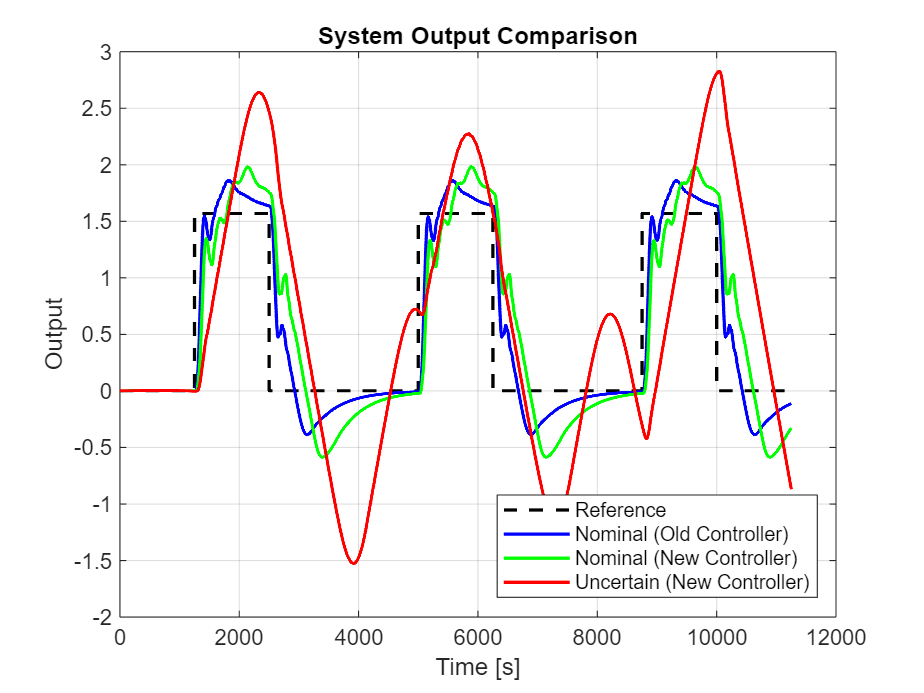


% Plot
figure;
plot(t, ref, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y_nominel_old, 'b', 'LineWidth', 1.5);
plot(t, y_nominel_new, 'g', 'LineWidth', 1.5);
plot(t, y_uncertain_new, 'r', 'LineWidth', 1.5);
grid on;

% Labels and legend
xlabel('Time [s]');
ylabel('Output');
title('System Output Comparison');
legend('Reference', 'Nominal (Old Controller)', 'Nominal (New Controller)', 'Uncertain (New Controller)', 'Location', 'best');

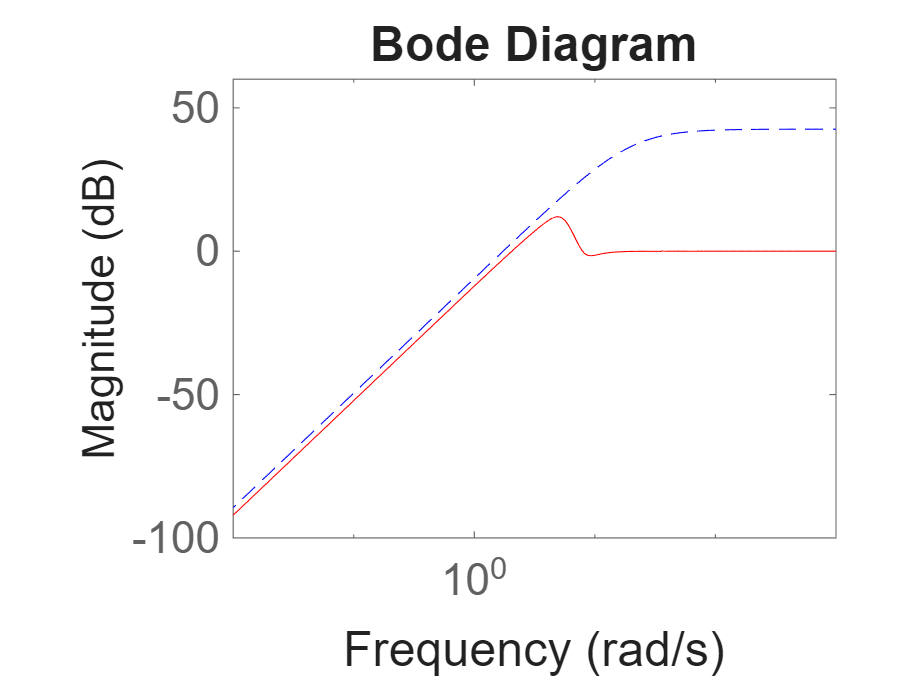






S_tf_new = feedback(1,G0_tf*tf(K_Hinf_new));
figure;
bodemag(S_tf_new,'r',Gam_new/(W1_new),'b--');

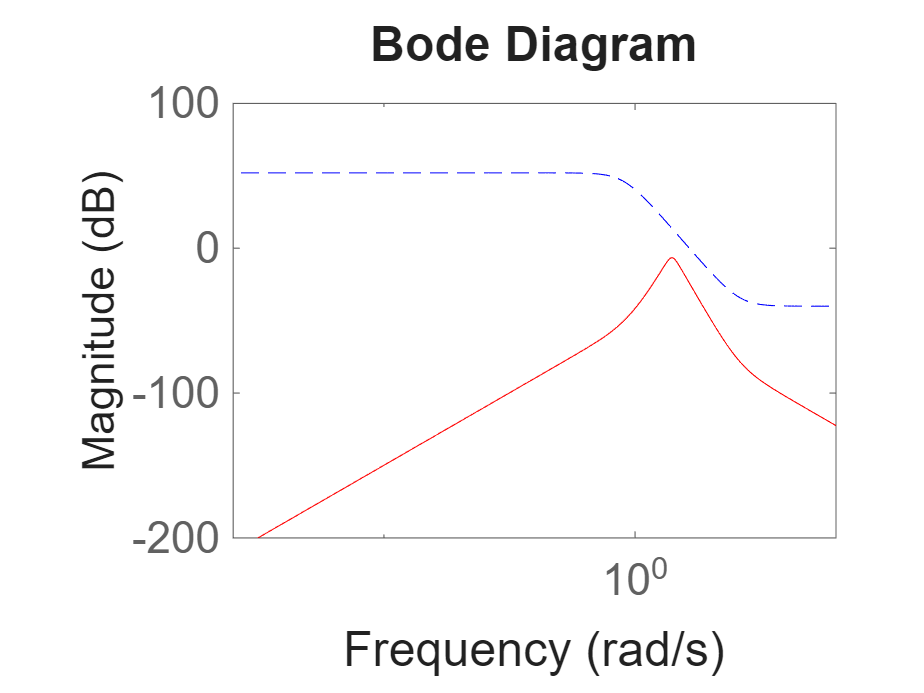


figure;
bodemag(K_Hinf_new*S_tf_new,'r',Gam/(W2_new),'b--');

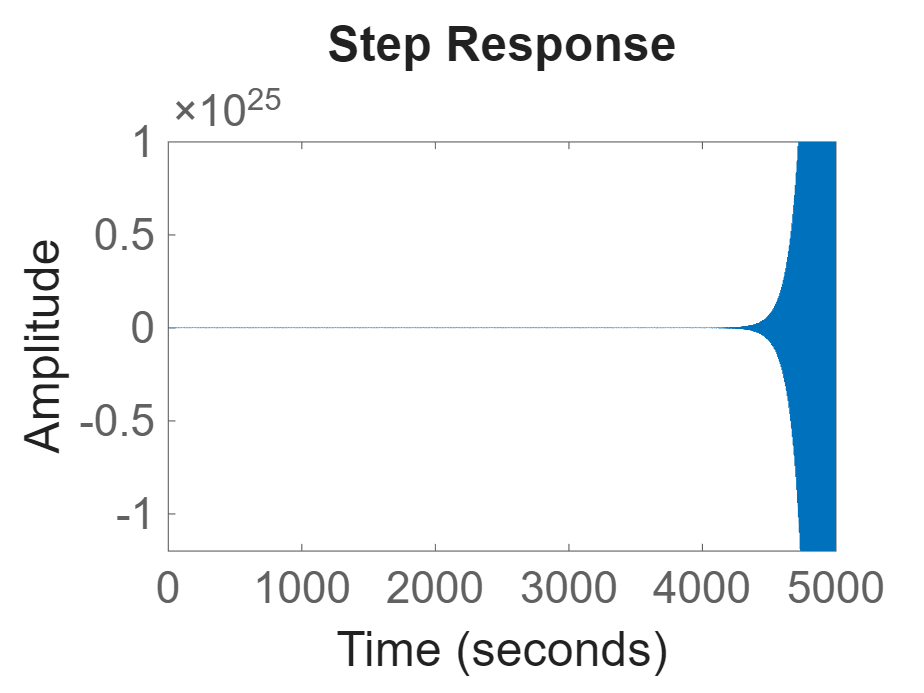

Cl_new = feedback(G_Jnew*K_Hinf_new,1);
figure;
step(Cl_new)

Cl_new2 = (G_Jnew*K_Hinf_new)/(1+G_Jnew*K_Hinf_new);
figure;
step(Cl_new2)


K_Hinf_new


K_Hinf_new =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10
   x1       -0.001   -0.000512   7.522e-15    9.63e-16    6.85e-16   7.937e-17   1.838e-15   2.027e-16   7.194e-15   9.558e-13
   x2    0.0004883  -2.907e-16   9.976e-18   1.277e-18   9.084e-19   1.053e-19   2.437e-18   2.688e-19   9.541e-18   1.056e-15
   x3      0.03005       86.98      -20.53      -1.485     -0.7088    -0.06385      -1.897     -0.1607      -7.353      -35.67
   x4   -1.086e-22  -4.494e-19         128   1.974e-21   1.404e-21   1.627e-22   3.768e-21   4.156e-22   1.475e-20   1.632e-18
   x5     0.003756       10.87       27.43       13.88      -1.479      -85.38      -3.067      -40.83      -6.345      -4.459
   x6   -2.154e-20  -8.156e-17   3.798e-18   4.634e-19          64   3.467e-20   8.384e-19   8.833e-20   3.274e-18   1.237e-16
   x7    -1.09e-19  -3.931e-16   2.115e-17   2.533e-18   1.672e-18          32   4.481e-

pole(K_Hinf_new)

ans =   -0.1210 +64.6933i
  -0.1210 -64.6933i
  -0.3123 +35.7371i
  -0.3123 -35.7371i
  -0.0005 + 0.0000i
  -0.0005 + 0.0000i
  -1.7491 + 7.9445i
  -1.7491 - 7.9445i
  -8.8241 + 4.1601i
  -8.8241 - 4.1601i


K_reduced_new = hankelmr(K_Hinf_new, order_desired);

Note: size(Gr) = 6, Order requested = 7. Reaching machine accuracy, see Help HANKELMR.


pole(K_reduced_new)

ans =   -0.0005 + 0.0000i
  -0.0005 - 0.0000i
  -1.7513 + 7.9456i
  -1.7513 - 7.9456i
  -8.6785 + 4.2739i
  -8.6785 - 4.2739i



% 
% 
% s = tf('s');
% 
% % Weight W1 (Sensitivity) - tracking requirement
% M = 2; A = 0.001; omega_star = 1;
% W1 = (s/M + omega_star)/(s + omega_star*A);
% 
% % Weight W2 (Control sensitivity) - limits control action
% % High-pass filter, scaled to reduce bandwidth
% W2 = (s + 0.5)/(0.05*s + 0.001);  % Tuned to limit fast response
% 
% % Weight W3 (Complementary sensitivity) - model uncertainty
% W3 = (0.833*s)/(s + 0.089);
% 
% % Scale W1 and W2 to push gamma below 1
% W1 = W1 / 1.1;
% W2 = W2 / 1.1;
% 
% % Plant (SISO top disk angle)
% G = ss(A,B,C,D);  % Already only top disk used
% 
% % H-infinity controller design
% [K_Hinf_robust, CL_robust, gamma_robust, info_robust] = mixsyn(G, W1, W2, W3, ...
%     'GMIN', 0.9, 'GMAX', 1.5, 'METHOD', 'lmi');
% 
% % Bode plots of closed-loop sensitivity functions
% L = G*K_Hinf_robust;
% S = feedback(1, L);
% T = feedback(L, 1);
% KS = K_Hinf_robust*S;
% 
% figure;
% bodemag(S, 'r', 1/W1, 'b--'); grid on;
% legend('Sensitivity S', '1/W1'); title('Sensitivity Function');
% 
% figure;
% bodemag(KS, 'r', 1/W2, 'b--'); grid on;
% legend('Control Sensitivity KS', '1/W2'); title('Control Sensitivity Function');
% 
% figure;
% bodemag(T, 'r', 1/W3, 'b--'); grid on;
% legend('Complementary Sensitivity T', '1/W3'); title('Model Uncertainty Handling');
% 
% % Step response analysis
% figure;
% step(feedback(G*K_Hinf_robust,1)); grid on;
% title('Closed-loop Step Response');
% 
% % Display gamma value
% disp(['Achieved gamma: ', num2str(gamma_robust)]);
% 
% 

Question 16

% 
% 
% % Use this in MATLAB to launch and simulate
% open_system('your_simulink_model');
% 
% % Set J1 in the base workspace for the model to use
% J1 = 0.0025;
% sim('your_simulink_model');
% 
% J1 = 0.0325;
% sim('your_simulink_model');
% 
% 
% 
% % Plot both responses for comparison:
% figure;
% plot(t_nominal, y_nominal, 'b', 'LineWidth', 1.5); hold on;
% plot(t_heavy, y_heavy, 'r--', 'LineWidth', 1.5);
% legend('Nominal J1', 'Increased J1');
% xlabel('Time (s)'); ylabel('Top Disk Angle (rad)');
% title('Step Response Comparison');
% grid on;
% 
% 
% 
% 



